% Rectangle
N = 256;  
rect_width = 25; 
rect_height = 50; 


rectangle = zeros(N, N);
center = N / 2;

rectangle(center-rect_height/2:center+rect_height/2, ...
          center-rect_width/2:center+rect_width/2) = 1;

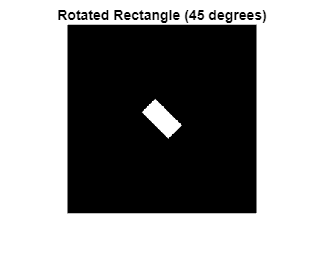

rotated_rectangle = imrotate(rectangle, 45, 'bilinear', 'crop');

figure;
imshow(rotated_rectangle);
title('Rotated Rectangle (45 degrees)');

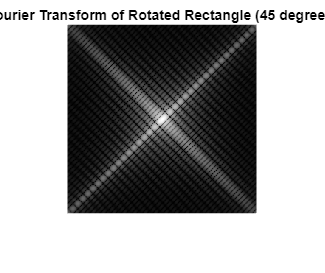


% Fourier Transform
ft_rotated_rect = fft2(rotated_rectangle);
ft_rotated_rect_shifted = fftshift(abs(ft_rotated_rect));
ft_rotated_rect_log = log(1 + ft_rotated_rect_shifted);

figure;
imshow(ft_rotated_rect_log, []);
title('Fourier Transform of Rotated Rectangle (45 degrees)');

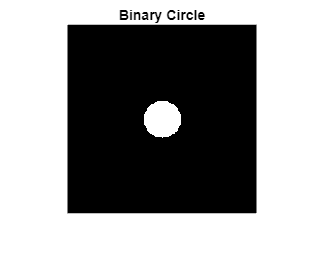

% Circle

N = 256;            
radius = 25;        
center = N/2 + 1;   
[X, Y] = meshgrid(1:N, 1:N);
dist_from_center = sqrt((X - center).^2 + (Y - center).^2);

circle = dist_from_center <= radius;

figure;
imshow(circle);
title('Binary Circle');

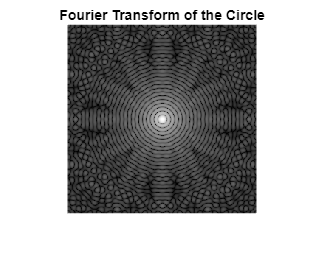


% Fourier Transform 
ft_circle = fft2(circle);
ft_circle_shifted = fftshift(abs(ft_circle));
ft_circle_log = log(1 + ft_circle_shifted);

figure;
imshow(ft_circle_log, []);
title('Fourier Transform of the Circle');

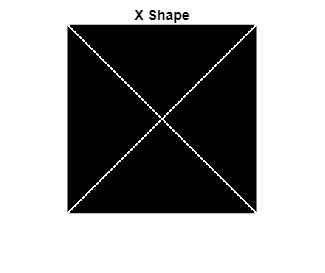

% X Image
N = 256;
[X, Y] = meshgrid(1:N, 1:N);
center = N/2;

line1 = abs(X - Y) <= 1; 
line2 = abs(X + Y - N - 1) <= 1;  
X_shape = line1 | line2;

figure;
imshow(X_shape);
title('X Shape');

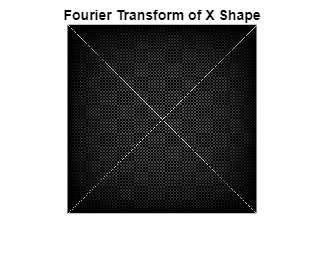


% Fourier Transform 
ft_X = fft2(X_shape);
ft_X_shifted = fftshift(abs(ft_X));
ft_X_log = log(1 + ft_X_shifted);

figure;
imshow(ft_X_log, []);
title('Fourier Transform of X Shape');